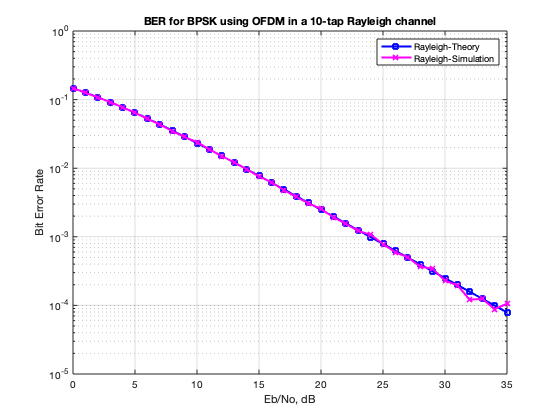

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% All rights reserved by Krishna Pillai, http://www.dsplog.com 
% The file may not be re-distributed without explicit authorization
% from Krishna Pillai.
% Checked for proper operation with Octave Version 3.0.0
% Author	: Krishna Pillai
% Email		: krishna@dsplog.com
% Version	: 1.0
% Date		: 05 June 2008
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Script for computing the BER for BPSK in OFDM modulation in the 
% presence of Rayeligh fading channel

clear all
nFFT        = 64; % fft size
nDSC        = 52; % number of data subcarriers
nBitPerSym  = 52; % number of bits per OFDM symbol (same as the number of subcarriers for BPSK)
nSym        = 10^4; % number of symbols

EbN0dB      = [0:35]; % bit to noise ratio
EsN0dB      = EbN0dB + 10*log10(nDSC/nFFT) + 10*log10(64/80); % converting to symbol to noise ratio

for ii = 1:length(EbN0dB)

   % Transmitter
   ipBit = rand(1,nBitPerSym*nSym) > 0.5; % random 1's and 0's
   ipMod = 2*ipBit-1; % BPSK modulation 0 --> -1, 1 --> +1
   ipMod = reshape(ipMod,nBitPerSym,nSym).'; % grouping into multiple symbolsa

   % Assigning modulated symbols to subcarriers from [-26 to -1, +1 to +26]
   xF = [zeros(nSym,6) ipMod(:,[1:nBitPerSym/2]) zeros(nSym,1) ipMod(:,[nBitPerSym/2+1:nBitPerSym]) zeros(nSym,5)] ;
   
   % Taking FFT, the term (nFFT/sqrt(nDSC)) is for normalizing the power of transmit symbol to 1 
   xt = (nFFT/sqrt(nDSC))*ifft(fftshift(xF.')).';

   % Appending cylic prefix
   xt = [xt(:,[49:64]) xt];

   % multipath channel
   nTap = 10;
   ht = 1/sqrt(2)*1/sqrt(nTap)*(randn(nSym,nTap) + j*randn(nSym,nTap));
   
   % computing and storing the frequency response of the channel, for use at recevier
   hF = fftshift(fft(ht,64,2));

   % convolution of each symbol with the random channel
   for jj = 1:nSym
      xht(jj,:) = conv(ht(jj,:),xt(jj,:));
   end
   xt = xht;

   % Concatenating multiple symbols to form a long vector
   xt = reshape(xt.',1,nSym*(80+nTap-1));

   % Gaussian noise of unit variance, 0 mean
   nt = 1/sqrt(2)*[randn(1,nSym*(80+nTap-1)) + j*randn(1,nSym*(80+nTap-1))];

   % Adding noise, the term sqrt(80/64) is to account for the wasted energy due to cyclic prefix
   yt = sqrt(80/64)*xt + 10^(-EsN0dB(ii)/20)*nt;

   % Receiver
   yt = reshape(yt.',80+nTap-1,nSym).'; % formatting the received vector into symbols
   yt = yt(:,[17:80]); % removing cyclic prefix

   % converting to frequency domain
   yF = (sqrt(nDSC)/nFFT)*fftshift(fft(yt.')).'; 

   % equalization by the known channel frequency response
   yF = yF./hF;

   % extracting the required data subcarriers
   yMod = yF(:,[6+[1:nBitPerSym/2] 7+[nBitPerSym/2+1:nBitPerSym] ]); 

   % BPSK demodulation
   % +ve value --> 1, -ve value --> -1
   ipModHat = 2*floor(real(yMod/2)) + 1;
   ipModHat(find(ipModHat>1)) = +1;
   ipModHat(find(ipModHat<-1)) = -1;

   % converting modulated values into bits
   ipBitHat = (ipModHat+1)/2;
   ipBitHat = reshape(ipBitHat.',nBitPerSym*nSym,1).';

   % counting the errors
   nErr(ii) = size(find(ipBitHat - ipBit),2);

end

simBer = nErr/(nSym*nBitPerSym);
EbN0Lin = 10.^(EbN0dB/10);
theoryBer = 0.5.*(1-sqrt(EbN0Lin./(EbN0Lin+1)));

close all; figure
semilogy(EbN0dB,theoryBer,'bs-','LineWidth',2);
hold on
semilogy(EbN0dB,simBer,'mx-','LineWidth',2);
axis([0 35 10^-5 1])
grid on
legend('Rayleigh-Theory', 'Rayleigh-Simulation');
xlabel('Eb/No, dB')
ylabel('Bit Error Rate')
title('BER for BPSK using OFDM in a 10-tap Rayleigh channel')